# Horizontal displacement & rotation code

## Import data (from camera 1)

%%% Imports data
Dataset_Hor_Rot = 'Horizontal_Displacement_and_Rotation';
Dataset_Hor_Rot_abrv = 'Hor. Disp. & Rot.';
Camera_Hor_Rot = 'cam1_4.mat';

camData_Hor_Rot = importCamData(Dataset_Hor_Rot,Camera_Hor_Rot);


## Camera 1

### Shows uncropped and cropped frame in colour

%%% Shows uncropped and cropped frame in colour
frame_Hor_Rot = 1

frame_Hor_Rot = 1

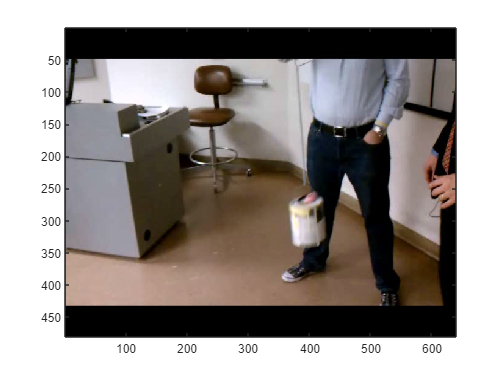


camImage_Hor_Rot = image(camData_Hor_Rot.vidFrames1_4(:,:,:,frame_Hor_Rot));

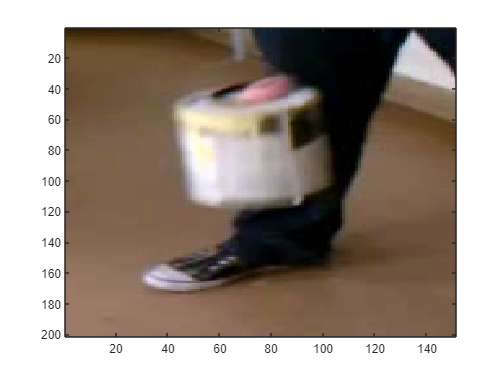

width_Hor_Rot = 325:475;
height_Hor_Rot = 225:425;
croppedFrame_Hor_Rot = camData_Hor_Rot.vidFrames1_4(height_Hor_Rot,width_Hor_Rot,:,frame_Hor_Rot);
croppedFrame1_Hor_Rot = camData_Hor_Rot.vidFrames1_4(height_Hor_Rot,width_Hor_Rot,:,1);
camImageCropped_Hor_Rot = image(croppedFrame_Hor_Rot);

### Shows frame of grayscale image

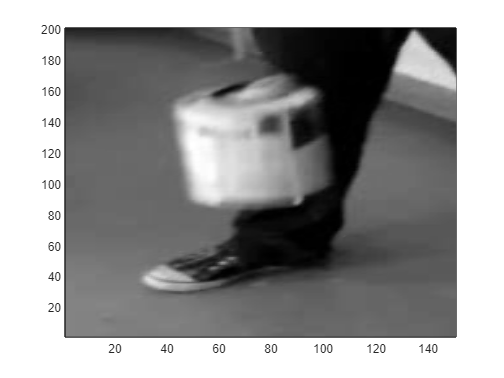

%%% Shows a frame from any camera as a grayscale colourmap (to locate
%%% locations of particular points

%%% Modified from: Data-Driven Modeling & Scientific Computation: 
%%% Methods for Complex Systems & Big Data 
%%% by J. NATHAN KUTZ


a_Hor_Rot = flipud( double( rgb2gray( camData_Hor_Rot.vidFrames1_4(height_Hor_Rot,width_Hor_Rot,:,1) )));
% a_Hor_Rot = flipud( double( rgb2gray( camData_Hor_Rot_2.vidFrames2_4(height_Hor_Rot_2,width_Hor_Rot_2,:,1) )));
% a_Hor_Rot = flipud( double( rgb2gray( camData_Hor_Rot_3.vidFrames3_4(height_Hor_Rot_3,width_Hor_Rot_3,:,1) )));

% x = 1:640;
% y = 1:480;
% [X,Y]=meshgrid(x,y);
% pcolor(X,Y,a)
pcolor(a_Hor_Rot)
shading interp
colormap("gray")

% set(gca,'Xtick',[],'Ytick',[],'Ztick',[])


### Finds and shows cap pixels (using both methods)

%%% Finds and shows cap pixels
x_Hor_Rot = 57;
y_Hor_Rot = 140;


r_Hor_Rot = croppedFrame1_Hor_Rot(end-y_Hor_Rot,x_Hor_Rot,1)

r_Hor_Rot = uint8
253

g_Hor_Rot = croppedFrame1_Hor_Rot(end-y_Hor_Rot,x_Hor_Rot,2)

g_Hor_Rot = uint8
236

b_Hor_Rot = croppedFrame1_Hor_Rot(end-y_Hor_Rot,x_Hor_Rot,3)

b_Hor_Rot = uint8
195

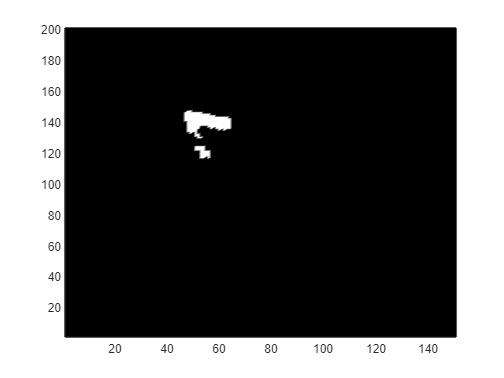


d_Hor_Rot = 20;
cap_Pixels_Hor_Rot = ((croppedFrame_Hor_Rot(:,:,1) >= r_Hor_Rot - d_Hor_Rot) & (croppedFrame_Hor_Rot(:,:,1) <= r_Hor_Rot + d_Hor_Rot)) ...
            &((croppedFrame_Hor_Rot(:,:,2) >= g_Hor_Rot - d_Hor_Rot) & (croppedFrame_Hor_Rot(:,:,2) <= g_Hor_Rot + d_Hor_Rot)) ...
            &((croppedFrame_Hor_Rot(:,:,3) >= b_Hor_Rot - d_Hor_Rot) & (croppedFrame_Hor_Rot(:,:,3) <= b_Hor_Rot + d_Hor_Rot));

pcolor(flipud(cap_Pixels_Hor_Rot))
shading interp
colormap("gray")

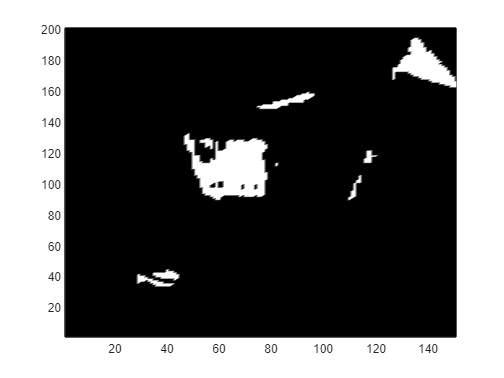


cap_Pixels_Hor_Rot_2 = getCapPixelsBright(croppedFrame_Hor_Rot,d_Hor_Rot);

pcolor(flipud(cap_Pixels_Hor_Rot_2))
shading interp
colormap("gray")

### Finds x and y coordinate of average of cap pixels

%%% Finds x and y coordinate of average of cap pixels
bounds_Hor_Rot = Boundaries(cap_Pixels_Hor_Rot)

bounds_Hor_Rot = 146

[top_Hor_Rot,bottom_Hor_Rot,left_Hor_Rot,right_Hor_Rot] = Boundaries(cap_Pixels_Hor_Rot)

top_Hor_Rot = 146

bottom_Hor_Rot = 116

left_Hor_Rot = 47

right_Hor_Rot = 64


[x_Hor_Rot,y_Hor_Rot] = centre(top_Hor_Rot,bottom_Hor_Rot,left_Hor_Rot,right_Hor_Rot)

x_Hor_Rot = 55.5000

y_Hor_Rot = 131

[x_avg_Hor_Rot,y_avg_Hor_Rot] = centre_avg(cap_Pixels_Hor_Rot)

x_avg_Hor_Rot = 54.4810

y_avg_Hor_Rot = 136.1190

### Finds position of cap and stores it into a vector

%%% Finds position of cap and stores it into a vector
numFrames_Hor_Rot = size(camData_Hor_Rot.vidFrames1_4(1,1,1,:),4);
% width_Hor_Rot = 325:475;
% height_Hor_Rot = 225:425;
croppedFrame1_Hor_Rot = camData_Hor_Rot.vidFrames1_4(height_Hor_Rot,width_Hor_Rot,:,1);

x_Hor_Rot = 53;
y_Hor_Rot = 140;
d_Hor_Rot = 20;

X_0_Hor_Rot = zeros(1,numFrames_Hor_Rot);
Y_0_Hor_Rot = zeros(1,numFrames_Hor_Rot);

for i = 1:numFrames_Hor_Rot
    croppedFrame_Hor_Rot = camData_Hor_Rot.vidFrames1_4(height_Hor_Rot,width_Hor_Rot,:,i);
    cap_Pixels_Hor_Rot = getCapPixels(croppedFrame1_Hor_Rot,croppedFrame_Hor_Rot,x_Hor_Rot,y_Hor_Rot,d_Hor_Rot);
    
    [x_avg_Hor_Rot,y_avg_Hor_Rot] = centre_avg(cap_Pixels_Hor_Rot);
    X_0_Hor_Rot(i) = x_avg_Hor_Rot;
    Y_0_Hor_Rot(i) = y_avg_Hor_Rot;
end

X_0_Hor_Rot

X_0_Hor_Rot =    53.5438   53.5069   53.7867   53.6636   53.7798   53.6636   53.6636   57.3989   62.5744   62.4845   66.5652   68.1718   68.1963   69.8000   70.9811   71.1308   70.8816   71.7073   71.7073   73.4211   74.5000   75.4000   75.0000       NaN       NaN   87.0000   75.2500   74.0000   71.2000   68.2500   68.0000   61.0000   58.6818   57.1579   53.5152   48.0000   47.9388   42.7597   37.9941   37.8471   34.4927   31.0675   31.0080   27.4161   24.6171   24.6101   21.0662   17.7229   17.7692   16.6776


Y_0_Hor_Rot

Y_0_Hor_Rot =   132.9078  132.9355  133.2938  133.0876  133.1239  133.0876  133.0876  141.9382  145.0974  144.9124  148.1932  150.6503  150.5767  151.4667  149.1887  149.0654  145.3947  138.7805  138.7805  129.7368  116.5000  114.6000   99.5000       NaN       NaN   66.0000   66.7500   70.3333   58.8000   55.0000   53.2000   59.1667   68.2727   66.7895   76.5455   80.4900   80.6735   87.2791   91.8639   91.7294   97.1073  102.9603  103.0161  111.2685  118.3165  118.2421  128.1150  140.2468  140.2137  148.1542


### Plots X and Y for camera 1

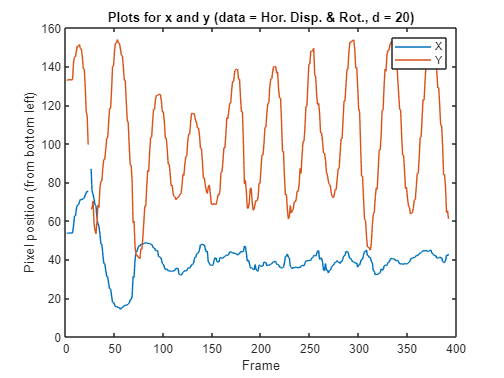

%%% Plots X and Y
plot(X_0_Hor_Rot)
title('Plots for x and y (data = Hor. Disp. & Rot., d = 20)')
xlabel('Frame')
ylabel('Pixel position (from bottom left)')
hold on
plot(Y_0_Hor_Rot)
legend('X','Y')
hold off

### Finds and plots X and Y for camera 1 for any d (with function that uses initial position)

%%% Finds and plots X and Y for any d (with function)
% width_Hor_Rot = 325:475;
% height_Hor_Rot = 225:425;

% x_Hor_Rot = 76;
% y_Hor_Rot = 157;
x_Hor_Rot = 57;
y_Hor_Rot = 140;
d1_Hor_Rot = 50;

[X_11_Hor_Rot,Y_11_Hor_Rot] = getXY(camData_Hor_Rot.vidFrames1_4,width_Hor_Rot,height_Hor_Rot,x_Hor_Rot,y_Hor_Rot,d1_Hor_Rot)

X_11_Hor_Rot =    75.8208   75.8197   76.0629   75.9942   75.9604   75.9953   75.9598   79.1557   82.7750   82.9251   86.1383   89.0528   89.0970   92.5020   94.7384   94.8478   98.2168  100.3130  100.3962  101.8259  103.1510  103.0786  102.6542  101.7349  102.0203  101.7436  100.6481  100.5675   98.2728   93.9460   94.0196   88.5492   83.8430   83.9832   78.7362   74.6784   74.6671   70.4266   67.2345   67.1012   64.7270   62.5037   62.4009   59.9463   58.3587   58.4051   54.9542   52.8975   52.9994   52.1797


Y_11_Hor_Rot =   130.8890  130.9861  131.1002  131.0699  130.9988  131.0857  130.9994  134.3784  136.4573  136.5884  136.7691  136.4219  136.3954  134.5831  133.2521  133.1864  132.7907  130.2378  130.0664  125.7115  121.7287  121.7563  117.8151  115.4789  115.8386  114.8376  113.6282  113.2276  109.9747  103.7414  103.7602   99.7057   98.7435   99.0467   98.8730  100.1611  100.1775  103.4805  108.3320  108.2084  113.6586  119.1303  119.0282  125.0642  130.8382  130.9352  135.5161  139.8542  139.8986  142.8424


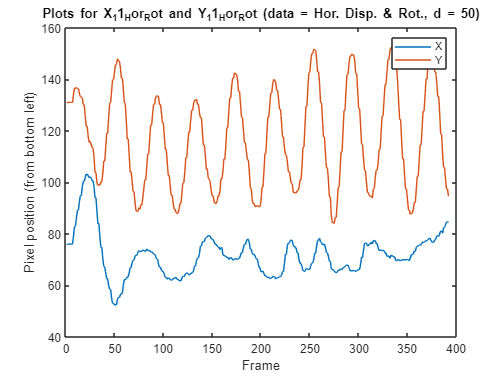

% X_11_Hor_Rot = X_11_Hor_Rot+width_Hor_Rot(1);
% Y_11_Hor_Rot = Y_11_Hor_Rot+height_Hor_Rot(1);

plotXY(X_11_Hor_Rot,Y_11_Hor_Rot,d1_Hor_Rot,Dataset_Hor_Rot_abrv)

### Finds and plots X and Y for camera 1 for any d (with function that uses brightness)

%%% Finds and plots X and Y for any d (with function)
% width_Hor_Rot = 325:475;
% height_Hor_Rot = 225:425;
d2_Hor_Rot = 20;

[X_12_Hor_Rot,Y_12_Hor_Rot] = getXYBright(camData_Hor_Rot.vidFrames1_4,width_Hor_Rot,height_Hor_Rot,d2_Hor_Rot)

X_12_Hor_Rot =    84.3172   84.3479   84.2697   84.0787   84.1277   84.0572   84.1653   86.5992   89.0658   89.1217   90.7252   92.9572   93.0312   95.9792   97.0234   97.1008   98.2001   98.5737   98.8643   98.3131   97.2932   97.1932   96.0928   94.8690   94.9047   92.7306   91.1714   90.9723   90.1684   89.0009   88.9353   86.3693   83.7896   83.8293   84.0272   84.5573   84.4759   85.3330   86.1069   85.7779   84.6217   83.2717   83.4385   81.3316   78.9321   79.2106   76.5238   69.7597   69.8074   65.1343


Y_12_Hor_Rot =   123.8715  123.9771  124.5806  124.2548  124.3416  124.1828  124.4219  126.6240  128.6331  128.6677  129.7148  130.0608  130.0042  128.4869  126.5274  126.6290  122.8313  117.8612  118.1381  112.5902  109.5489  109.4886  106.7493  104.1858  104.1724  102.2068  101.0755  100.8615   99.7662  100.0660   99.8671   99.7074   99.8252  100.0122  104.8165  110.1097  109.9853  116.9087  125.4002  124.9322  131.4403  136.2596  136.5956  141.0396  144.3822  144.2497  146.2460  145.0631  145.1964  143.3409


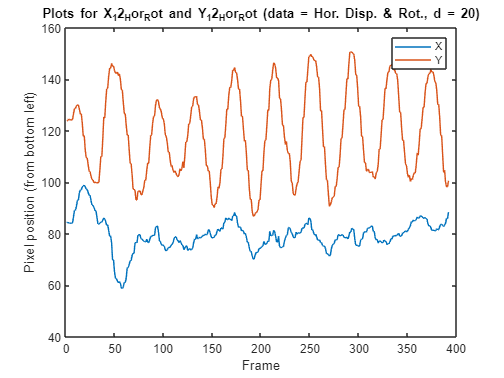


plotXY(X_12_Hor_Rot,Y_12_Hor_Rot,d2_Hor_Rot,Dataset_Hor_Rot_abrv)

## Camera 2

### Imports data

%%% Imports data from second camera
Camera_Hor_Rot_2 = 'cam2_4.mat';

camData_Hor_Rot_2 = importCamData(Dataset_Hor_Rot,Camera_Hor_Rot_2);


### Shows uncropped and cropped frame in colour

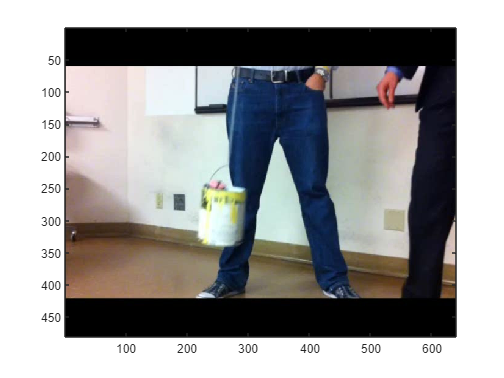

%%% Shows uncropped and cropped frame in colour for 2nd camera
frame_Hor_Rot_2 = 1;

camImage_Hor_Rot_2 = image(camData_Hor_Rot_2.vidFrames2_4(:,:,:,frame_Hor_Rot_2));

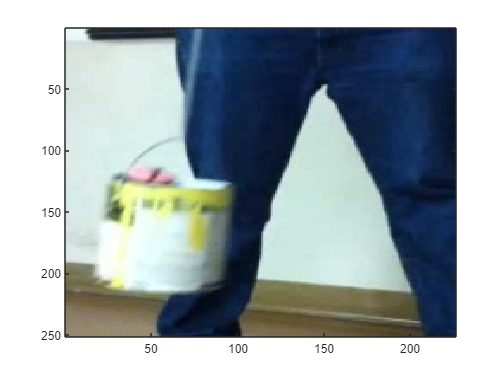

width_Hor_Rot_2 = 200:425;
height_Hor_Rot_2 = 125:375;
croppedFrame_Hor_Rot_2 = camData_Hor_Rot_2.vidFrames2_4(height_Hor_Rot_2,width_Hor_Rot_2,:,frame_Hor_Rot_2);
camImageCropped_Hor_Rot_2 = image(croppedFrame_Hor_Rot_2);

### Finds and plots X and Y for camera 2 (using initial position)

%%% Finds and plots X and Y for camera 2
% width_Hor_Rot_2 = 200:400;
% % height_Hor_Rot_2 = 175:400;

% x_Hor_Rot_2 = 45;
% y_Hor_Rot_2 = 133;
x_Hor_Rot_2 = 37;
y_Hor_Rot_2 = 117;
d1_Hor_Rot_2 = 50;

[X_21_Hor_Rot,Y_21_Hor_Rot] = getXY(camData_Hor_Rot_2.vidFrames2_4,width_Hor_Rot_2,height_Hor_Rot_2,x_Hor_Rot_2,y_Hor_Rot_2,d1_Hor_Rot_2)

X_21_Hor_Rot =    51.1240   51.0130   56.6645   64.0131   69.5007   74.5553   74.4621   83.7991   91.0046   98.3110  104.7179  104.6186  111.0979  117.1204  123.0206  127.8361  127.6673  132.9104  137.2830  139.6659  141.7070  141.3220  141.9815  142.5274  140.2843  138.7985  138.4102  137.3383  134.4985  130.7711  132.4189  132.8839  138.0446  147.3435  142.7608  142.3474  141.8145  139.3032  129.7206  121.8810  112.9305  112.8288  108.1401  102.5474   95.6939   95.7321   90.7674   85.7978   80.8376   76.9609


Y_21_Hor_Rot =   102.9520  103.0140  107.2676  115.5238  128.6508  136.7035  136.7247  147.6623  157.8084  169.3014  178.8415  178.9770  186.8401  194.4266  200.0471  202.4056  202.3346  203.7353  202.8446  200.5627  199.1341  198.5606  195.9243  191.6478  178.8750  169.6241  168.2767  158.7270  145.6716  137.4437  123.6577  122.9152  115.1139  108.5435  101.3898   94.8568   94.9880   91.1004   90.8676   91.2288   93.7444   94.3740   97.4484   99.7218  104.4799  104.4733  112.8026  124.5647  134.6402  147.2204


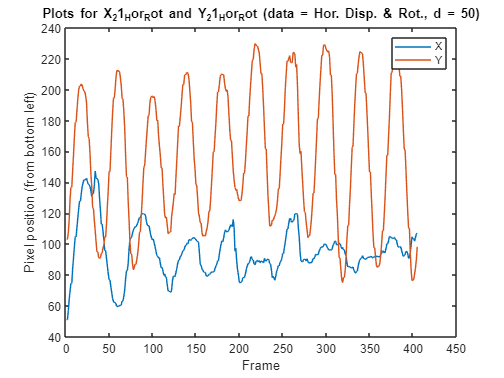


plotXY(X_21_Hor_Rot,Y_21_Hor_Rot,d1_Hor_Rot_2,Dataset_Hor_Rot_abrv)

### Finds and plots X and Y for camera 2 (using brightness)

%%% Finds and plots X and Y for camera 2
% width_Hor_2 = 200:400;
% height_Hor_2 = 175:400;
d2_Hor_Rot_2 = 20;

[X_22_Hor_Rot,Y_22_Hor_Rot] = getXYBright(camData_Hor_Rot_2.vidFrames2_4,width_Hor_Rot_2,height_Hor_Rot_2,d2_Hor_Rot_2)

X_22_Hor_Rot =    82.1179   82.0286   74.2778   64.8664   62.8654   58.9223   59.6462   58.7644   57.1331   59.7545   59.7126   60.5454   60.6661   62.2042   61.7691   59.5929   59.2688   58.6645   59.7842   62.0707   63.6944   63.6647   64.3158   67.1540   67.6863   67.5811   67.6536   69.4798   67.0665   66.6419   65.3237   65.2828   63.0911   60.4385   59.5318   59.5701   59.4692   60.2804   61.2869   62.9082   63.8696   63.5501   64.7860   62.7722   62.4332   63.0583   63.2994   64.8768   65.7153   69.4427


Y_22_Hor_Rot =    92.3185   91.6243  101.2683  114.0402  121.3759  126.9812  126.9804  131.8047  136.2196  139.0984  141.9653  141.3009  143.9566  146.6797  147.8309  151.1989  151.2897  152.8497  152.8836  154.1063  154.5296  154.8192  154.5190  154.6014  151.9260  148.6681  148.4178  144.6623  143.5740  142.3371  139.1774  138.7980  137.4342  137.9324  135.8459  134.4431  134.3687  134.4674  134.7203  133.1134  133.1609  133.0940  133.4332  133.7556  132.2442  131.8505  132.6132  128.3433  128.8018  128.8342


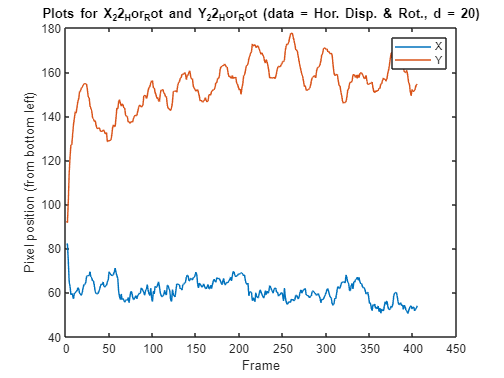


plotXY(X_22_Hor_Rot,Y_22_Hor_Rot,d2_Hor_Rot_2,Dataset_Hor_Rot_abrv)

## Camera 3

### Import data

%%% Imports data from third camera
Camera_Hor_Rot_3 = 'cam3_4.mat';

camData_Hor_Rot_3 = importCamData(Dataset_Hor_Rot,Camera_Hor_Rot_3);


### Shows uncropped and cropped frame in colour

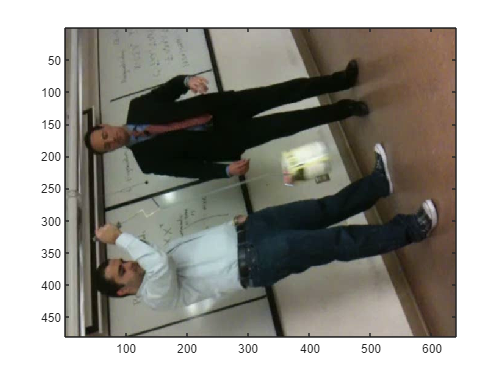

%%% Shows uncropped and cropped frame in colour for 2nd camera
frame_Hor_Rot_3 = 1;

camImage_Hor_Rot_3 = image(camData_Hor_Rot_3.vidFrames3_4(:,:,:,frame_Hor_Rot_3));

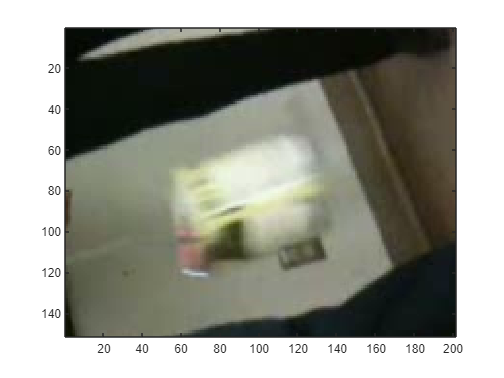

width_Hor_Rot_3 = 300:500;
height_Hor_Rot_3 = 125:275;
croppedFrame_Hor_Rot_3 = camData_Hor_Rot_3.vidFrames3_4(height_Hor_Rot_3,width_Hor_Rot_3,:,frame_Hor_Rot_3);
camImageCropped_Hor_Rot_3 = image(croppedFrame_Hor_Rot_3);

### Finds and plots X and Y for camera 3 (using initial position)

%%% Finds and plots X and Y for camera 3
% width_Hor_Rot_3 = 300:500;
% height_Hor_Rot_3 = 125:275;

% x_Hor_Rot_3 = 68;
% y_Hor_Rot_3 = 37;
x_Hor_Rot_3 = 77;
y_Hor_Rot_3 = 55;
d1_Hor_Rot_3 = 50;

[X_31_Hor_Rot,Y_31_Hor_Rot] = getXY(camData_Hor_Rot_3.vidFrames3_4,width_Hor_Rot_3,height_Hor_Rot_3,x_Hor_Rot_3,y_Hor_Rot_3,d1_Hor_Rot_3)

X_31_Hor_Rot =    93.1800   93.2477   83.3854   83.3420   72.2264   72.2116   63.0198   57.4056   57.3621   53.6668   53.5577   53.4426   53.5543   55.3018   58.6655   58.8636   65.4459   65.6714   73.8551   73.8413   83.1313   93.4713   92.9827  101.6963  101.6645  110.6915  110.4459  116.7932  119.9136  119.2827  122.9083  123.1018  126.9937  127.0691  130.2701  130.3744  130.1573  125.5530  125.6536  118.3091  118.0196  111.0700  105.3396  105.4316   98.9498   98.8427   93.9048   93.7665   91.5783   89.7593


Y_31_Hor_Rot =    74.9264   74.9165   76.2641   76.1075   78.3777   78.3202   80.4423   83.5860   83.6220   86.2330   86.2421   88.0788   88.1681   89.8734   90.2846   90.3898   90.2935   90.3839   89.4596   89.5573   90.6089   93.3655   94.5066   93.5759   93.4050   93.9060   93.9124   96.5876   96.8635   97.0769   95.4145   95.4585   90.9226   90.8344   81.4219   74.4424   74.4178   69.3644   68.8450   61.4540   62.1501   55.2012   46.1019   46.1206   42.9302   42.9240   41.1501   41.3406   39.0801   37.9947


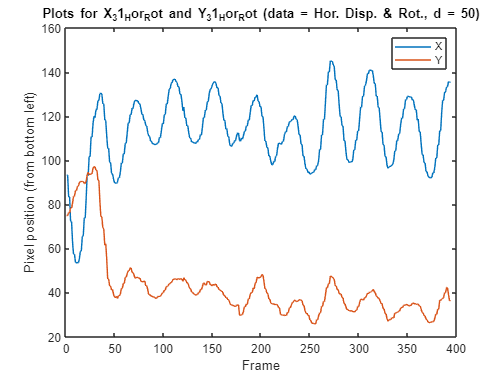


plotXY(X_31_Hor_Rot,Y_31_Hor_Rot,d1_Hor_Rot_3,Dataset_Hor_Rot_abrv)

### Finds and plots X and Y for camera 3 (using brightness)

%%% Finds and plots X and Y for camera 3
% width_Hor_Rot_3 = 300:500;
% height_Hor_Rot_3 = 125:275;
d2_Hor_Rot_3 = 20;

[X_32_Hor_Rot,Y_32_Hor_Rot] = getXYBright(camData_Hor_Rot_3.vidFrames3_4,width_Hor_Rot_3,height_Hor_Rot_3,d2_Hor_Rot_3)

X_32_Hor_Rot =   131.5978  129.4197  128.2321  128.5541  122.6176  122.5391  120.6832  121.6362  121.5975  127.4013  127.1632  125.1567  124.3693  122.7328  119.5493  119.2641  119.4781  118.9766  118.5734  118.3305  125.9081  125.2035  124.9659  125.7846  125.8083  125.5613  126.8539  122.5082  120.6178  121.1368  126.5876  125.9113  125.7801  127.4534  132.0615  129.4841  129.6322  129.5115  131.7370  131.8968  130.7410  122.4015  124.9688  125.6245  125.2334  125.3661  121.8497  120.1084  121.8141  122.2930


Y_32_Hor_Rot =    86.1376   85.9460   83.2791   83.3657   79.8751   79.9033   77.8074   76.9292   77.2620   76.0081   76.0900   76.4774   76.2896   73.2744   75.7232   75.9515   77.9270   77.7580   75.3771   75.7131   74.8372   77.0862   77.2408   82.3169   82.4354   92.4355   93.5349  103.6625  106.8267  106.4087  107.3573  107.1319   99.1704   99.0226   92.5871   85.5795   85.6244   71.9221   72.9241   62.7184   61.8650   51.1739   48.7370   49.3114   47.1176   47.5026   44.3991   43.2478   42.6279   41.2128


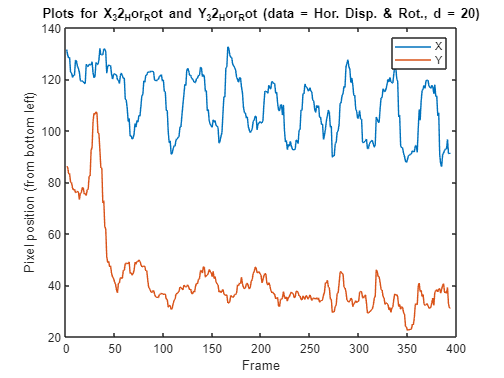


plotXY(X_32_Hor_Rot,Y_32_Hor_Rot,d2_Hor_Rot_3,Dataset_Hor_Rot_abrv)

## PCA

### Merge cameras' X and Y data

sz_Hor_Rot = min( [size(X_11_Hor_Rot,2), size(X_21_Hor_Rot,2), size(X_31_Hor_Rot,2)] )

sz_Hor_Rot = 392


X_Hor_Rot = cat( 1,X_11_Hor_Rot(1:sz_Hor_Rot),Y_11_Hor_Rot(1:sz_Hor_Rot),X_21_Hor_Rot(1:sz_Hor_Rot),Y_21_Hor_Rot(1:sz_Hor_Rot),X_31_Hor_Rot(1:sz_Hor_Rot),Y_31_Hor_Rot(1:sz_Hor_Rot) )

X_Hor_Rot =    75.8208   75.8197   76.0629   75.9942   75.9604   75.9953   75.9598   79.1557   82.7750   82.9251   86.1383   89.0528   89.0970   92.5020   94.7384   94.8478   98.2168  100.3130  100.3962  101.8259  103.1510  103.0786  102.6542  101.7349  102.0203  101.7436  100.6481  100.5675   98.2728   93.9460   94.0196   88.5492   83.8430   83.9832   78.7362   74.6784   74.6671   70.4266   67.2345   67.1012   64.7270   62.5037   62.4009   59.9463   58.3587   58.4051   54.9542   52.8975   52.9994   52.1797
  130.8890  130.9861  131.1002  131.0699  130.9988  131.0857  130.9994  134.3784  136.4573  136.5884  136.7691  136.4219  136.3954  134.5831  133.2521  133.1864  132.7907  130.2378  130.0664  125.7115  121.7287  121.7563  117.8151  115.4789  115.8386  114.8376  113.6282  113.2276  109.9747  103.7414  103.7602   99.7057   98.7435   99.0467   98.8730  100.1611  100.1775  103.4805  108.3320  108.2084  113.6586  119.1303  119.0282  125.0642  130.8382  130.9352  135.5161  139.8542  139.8

### Do PCA on the data matrix (using SVD decomposition)

[~,Y_Hor_Rot,lambda_Hor_Rot] = pca(X_Hor_Rot.')

Y_Hor_Rot =   -50.2015  -23.9934  -42.2423  -40.0929   -6.1534   15.7332
  -50.1296  -23.9235  -42.3170  -40.1250   -6.2207   15.8284
  -44.4635  -32.0381  -42.0988  -39.1939   -2.0192   10.1129
  -36.4101  -33.7895  -36.2253  -35.4273   -2.3046    7.7661
  -22.2474  -41.4010  -34.3064  -36.6370    2.2562    0.9335
  -14.4320  -42.2800  -29.7470  -34.3614    2.0755   -0.6648
  -13.1542  -48.4872  -33.0888  -37.0874    5.8561   -4.6596
   -0.8933  -57.5109  -28.0241  -34.1281    7.1690   -6.0574
    9.5399  -60.6016  -22.0583  -30.1198    7.9792   -4.8048
   21.1030  -65.4303  -16.2355  -29.0582    8.4765   -8.5042


lambda_Hor_Rot = 	1.0e+03 *

    2.0839
    0.4463
    0.4257
    0.1627
    0.0389
    0.0255


Y_Hor_Rot = Y_Hor_Rot.'

Y_Hor_Rot =   -50.2015  -50.1296  -44.4635  -36.4101  -22.2474  -14.4320  -13.1542   -0.8933    9.5399   21.1030   30.4356   30.4043   38.0230   44.5713   49.1984   51.5231   50.3729   51.1493   49.1863   45.9314   42.0900   39.7901   36.2521   30.2932   18.2268    7.7217    6.1339   -4.1979  -18.0564  -27.6032  -41.0827  -42.9488  -50.8286  -56.7121  -63.6587  -69.1601  -69.0122  -70.9184  -70.1312  -68.4840  -64.9152  -61.3906  -57.2173  -53.6415  -46.6072  -46.5691  -36.7525  -24.5855  -14.6901   -1.7438
  -23.9934  -23.9235  -32.0381  -33.7895  -41.4010  -42.2800  -48.4872  -57.5109  -60.6016  -65.4303  -67.5515  -69.1332  -70.6429  -72.1690  -72.2490  -73.9194  -70.8093  -72.4495  -69.4052  -69.7728  -65.2491  -60.8603  -61.0433  -55.6079  -56.8959  -52.6115  -52.1311  -51.0013  -48.6933  -45.7392  -45.8919  -43.4237  -40.9135  -46.1615  -37.1537  -33.7053  -33.5598  -33.0533  -29.4044  -25.9569  -23.3976  -24.7109  -20.3830  -18.9425  -18.6063  -18.7251  -17.6537  -14.6280  -10.7

### Plot PCA components 

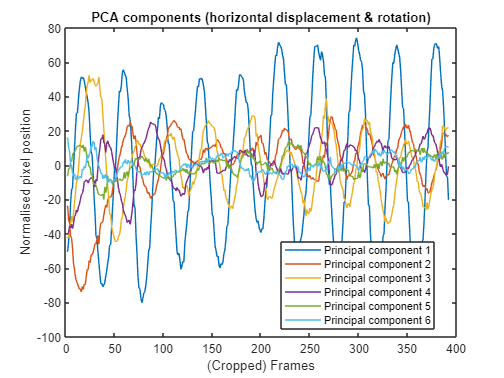

plot(Y_Hor_Rot(1,:))
title('PCA components (horizontal displacement & rotation)')
xlabel('(Cropped) Frames')
ylabel('Normalised pixel position')

hold on
plot(Y_Hor_Rot(2,:))
plot(Y_Hor_Rot(3,:))
plot(Y_Hor_Rot(4,:))
plot(Y_Hor_Rot(5,:))
plot(Y_Hor_Rot(6,:))
legend('Principal component 1', ...
       'Principal component 2', ...
       'Principal component 3', ...
       'Principal component 4', ...
       'Principal component 5', ...
       'Principal component 6','Location','best')
hold off

### Plots PCA eigenvalues

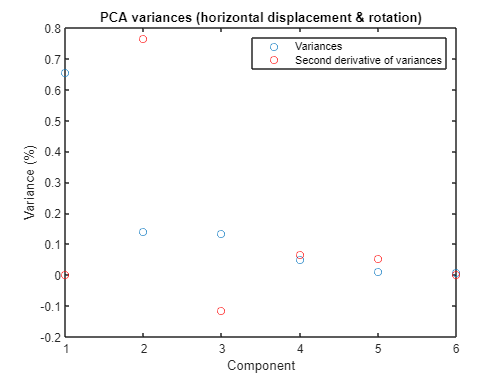

plot(lambda_Hor_Rot/sum(lambda_Hor_Rot), 'o')
title('PCA variances (horizontal displacement & rotation)')
xlabel('Component')
ylabel('Variance (%)')

ddlambda_Hor_Rot = zeros(size(lambda_Hor_Rot));
for i = 1:length(lambda_Hor_Rot)
    if i == 1
        ddlambda_Hor_Rot(i) = 0;
    elseif i == length(lambda_Hor_Rot)
        ddlambda_Hor_Rot(i) = 0;
    else
        ddlambda_Hor_Rot(i) = (lambda_Hor_Rot(i+1) - 2*lambda_Hor_Rot(i) + lambda_Hor_Rot(i-1));
    end
end

hold on
plot(ddlambda_Hor_Rot/sum(abs(ddlambda_Hor_Rot)), 'ro')
legend('Variances','Second derivative of variances')
hold off

## Analysis

### Gets fast fourier transforms of largest principal components 

%%% Modified from fft documentation

Fs_Hor_Rot = 1;            % Sampling frequency                    
T_Hor_Rot = 1/Fs_Hor_Rot;             % Sampling period       
L_Hor_Rot = sz_Hor_Rot;             % Length of signal
t_Hor_Rot = (0:L_Hor_Rot-1)*T_Hor_Rot;        % Time vector

f_1_Hor_Rot = fft(Y_Hor_Rot(1,:))

f_1_Hor_Rot = 	1.0e+04 *

   0.0000 + 0.0000i  -0.0827 + 0.1709i   0.1372 - 0.0581i   0.1066 + 0.0192i   0.1134 - 0.0240i   0.0314 + 0.0527i   0.1636 - 0.0015i   0.1517 - 0.0710i   0.1983 - 0.0411i   0.2746 + 0.0365i  -1.0587 + 0.3536i  -0.2418 + 0.0254i  -0.0592 + 0.0360i  -0.0536 - 0.0109i  -0.0456 + 0.0165i  -0.0551 - 0.0084i  -0.0579 + 0.0146i  -0.0397 + 0.0244i  -0.0087 - 0.0031i  -0.0052 + 0.0202i  -0.0305 + 0.0072i  -0.0247 - 0.0090i  -0.0133 + 0.0089i  -0.0079 - 0.0049i  -0.0142 + 0.0179i  -0.0144 + 0.0060i  -0.0183 + 0.0034i  -0.0149 + 0.0153i   0.0082 + 0.0123i  -0.0122 + 0.0244i  -0.0086 - 0.0084i   0.0051 + 0.0074i  -0.0213 + 0.0077i  -0.0094 - 0.0011i  -0.0031 + 0.0085i  -0.0144 + 0.0025i   0.0055 - 0.0049i  -0.0076 + 0.0083i  -0.0136 + 0.0054i  -0.0048 - 0.0052i   0.0099 - 0.0020i  -0.0112 + 0.0109i  -0.0093 - 0.0006i  -0.0042 - 0.0008i  -0.0048 + 0.0071i  -0.0014 - 0.0036i   0.0077 + 0.0080i  -0.0109 + 0.0083i   0.0001 - 0.0032i   0.0070 + 0.0047i


### Plot absolute values of the FFT

#### PC1

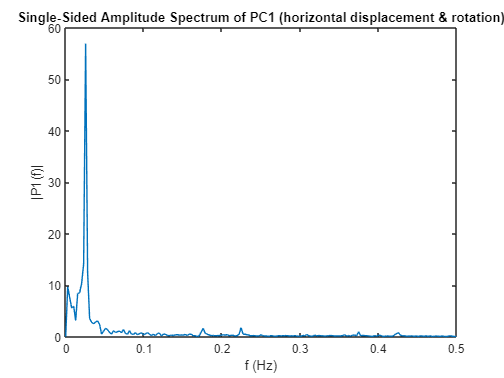

%%% Modified from fft documentation

P2_1_Hor_Rot = abs(f_1_Hor_Rot/L_Hor_Rot);
P1_1_Hor_Rot = P2_1_Hor_Rot(1:L_Hor_Rot/2+1);
P1_1_Hor_Rot(2:end-1) = 2*P1_1_Hor_Rot(2:end-1);

f1_Hor_Rot = Fs_Hor_Rot*(0:(L_Hor_Rot/2))/L_Hor_Rot;
plot(f1_Hor_Rot,P1_1_Hor_Rot) 
title('Single-Sided Amplitude Spectrum of PC1 (horizontal displacement & rotation)')
xlabel('f (Hz)')
ylabel('|P1(f)|')


P1_1_max_Hor_Rot = max(P1_1_Hor_Rot)

P1_1_max_Hor_Rot = 56.9487

f1_max_Hor_Rot = f1_Hor_Rot(P1_1_Hor_Rot == P1_1_max_Hor_Rot)

f1_max_Hor_Rot = 0.0255

### Use least square fitting to estimate sine waves for PCs (assuming simple harmonic motion)

#### PC1

%%% Minimise LSE: sum( abs( f(x_k)-y_k )^2 )
%%% Function: f(x) = A*sin(omega_n*x + phi)
xs_Hor_Rot = 1:sz_Hor_Rot;
LSE_sin_1_Hor_Rot = @(n) sum( abs( n(1)*sin(n(2)*xs_Hor_Rot + n(3))-Y_Hor_Rot(1,:) ).^2 );
n0_1_Hor_Rot = [P1_1_max_Hor_Rot, f1_max_Hor_Rot*2*pi, -90*(pi/180)];
coef_1_Hor_Rot = fminsearch(LSE_sin_1_Hor_Rot,n0_1_Hor_Rot)

coef_1_Hor_Rot =    62.3205    0.1568   -1.3257


Error_1_Hor_Rot = LSE_sin_1_Hor_Rot(coef_1_Hor_Rot)

Error_1_Hor_Rot = 6.2772e+04

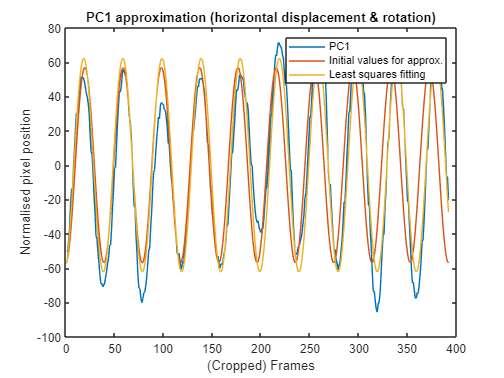


y_1_Hor_Rot = coef_1_Hor_Rot(1)*sin(coef_1_Hor_Rot(2)*xs_Hor_Rot + coef_1_Hor_Rot(3));
y0_1_Hor_Rot = n0_1_Hor_Rot(1)*sin(n0_1_Hor_Rot(2)*xs_Hor_Rot + n0_1_Hor_Rot(3));

plot(Y_Hor_Rot(1,:))
title('PC1 approximation (horizontal displacement & rotation)')
xlabel('(Cropped) Frames')
ylabel('Normalised pixel position')
hold on
plot(y0_1_Hor_Rot)
plot(y_1_Hor_Rot)
legend('PC1','Initial values for approx.', 'Least squares fitting')
hold off

#### PC1 (with multiple sine waves)

%%% Function: f(x) = A_1*sin(omega_n1*x + phi_1) 
%%%                + A_2*sin(omega_n2*x + phi_2)
xs_Hor_Rot = 1:sz_Hor_Rot;
LSE_sin_1_mult_Hor_Rot = @(n) sum( abs( (n(1)*sin(n(2)*xs_Hor_Rot + n(3)) ...
                                + n(4)*sin(n(5)*xs_Hor_Rot + n(6)) )-Y_Hor_Rot(1,:) ).^2 );
n0_1_mult_Hor_Rot = [P1_1_max_Hor_Rot, f1_max_Hor_Rot*2*pi, 180*(pi/180), ...
                     10, 0.00255102*2*pi, 90*(pi/180)];
coef_1_mult_Hor_Rot = fminsearch(LSE_sin_1_mult_Hor_Rot,n0_1_mult_Hor_Rot)

coef_1_mult_Hor_Rot =    62.6869    0.1568    4.9657   11.7001    0.0188    3.2519


Error_1_mult_Hor_Rot = LSE_sin_1_mult_Hor_Rot(coef_1_mult_Hor_Rot)

Error_1_mult_Hor_Rot = 3.6794e+04

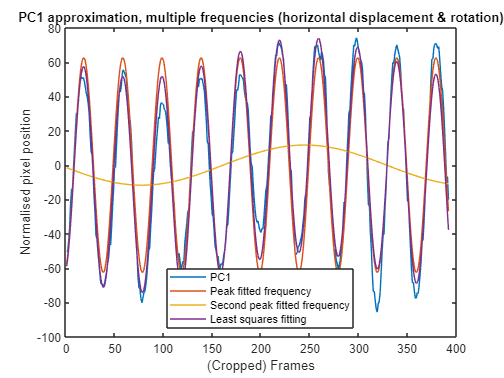


y_1_mult_Hor_Rot = coef_1_mult_Hor_Rot(1)*sin(coef_1_mult_Hor_Rot(2)*xs_Hor_Rot + coef_1_mult_Hor_Rot(3)) ...
             + coef_1_mult_Hor_Rot(4)*sin(coef_1_mult_Hor_Rot(5)*xs_Hor_Rot + coef_1_mult_Hor_Rot(6));
y_1_mult_a_Hor_Rot = coef_1_mult_Hor_Rot(1)*sin(coef_1_mult_Hor_Rot(2)*xs_Hor_Rot + coef_1_mult_Hor_Rot(3));
y_1_mult_b_Hor_Rot = coef_1_mult_Hor_Rot(4)*sin(coef_1_mult_Hor_Rot(5)*xs_Hor_Rot + coef_1_mult_Hor_Rot(6));

plot(Y_Hor_Rot(1,:))
title('PC1 approximation, multiple frequencies (horizontal displacement & rotation)')
xlabel('(Cropped) Frames')
ylabel('Normalised pixel position')
hold on
plot(y_1_mult_a_Hor_Rot)
plot(y_1_mult_b_Hor_Rot)
plot(y_1_mult_Hor_Rot)
legend('PC1','Peak fitted frequency','Second peak fitted frequency', ...
    'Least squares fitting','Location','best')
hold off

## Various functions are here:

### Imports data

function camData = importCamData(Dataset,Camera)

Data_path =join( ['C:' ...
    '\Users' ...
    '\dakin' ...
    '\Oscillating-Mass-and-Dimensionality-Reduction' ... 
    '\Project_Datasets' ...
    '\',Dataset, ... 
    '\',Camera] ); % Change to location of files

camData = load( Data_path );

end



### Shows cropped and uncropped video frame

%%% Shows cropped and uncropped video frame
function [im_1,im_2] = showFrames(frameNum,vidFrame,width,height)

normFrame = vidFrame(:,:,:,frameNum);
im_1 = image(normFrame);

croppedFrame = vidFrame(height,width,:,frameNum);
im_2 = image(croppedFrame);

end



### Finds pixel that corresponds to cap

%%% Finds the pixels that correspond to the cap
function cap_Pixels = getCapPixels(croppedFrame1,croppedFrame,x,y,d)

if nargin == 4
    d = 10;
elseif nargin == 2
    x = 82;
    y = 198;
end


r = croppedFrame1(end-y,x,1);
g = croppedFrame1(end-y,x,2);
b = croppedFrame1(end-y,x,3);


cap_Pixels = ((croppedFrame(:,:,1) >= r - d) & (croppedFrame(:,:,1) <= r + d)) ...
            &((croppedFrame(:,:,2) >= g - d) & (croppedFrame(:,:,2) <= g + d)) ...
            &((croppedFrame(:,:,3) >= b - d) & (croppedFrame(:,:,3) <= b + d));
end



### Finds the pixels that correspond to the cap using brightness

%%% Finds the pixels that correspond to the cap
function cap_Pixels = getCapPixelsBright(croppedFrame,d)

if nargin == 1
    d = 10;
end

br = max( rgb2gray(croppedFrame) );

cap_Pixels = ((croppedFrame(:,:,1) >= br - d) & (croppedFrame(:,:,1) <= br + d)) ...
            &((croppedFrame(:,:,2) >= br - d) & (croppedFrame(:,:,2) <= br + d)) ...
            &((croppedFrame(:,:,3) >= br - d) & (croppedFrame(:,:,3) <= br + d));
end

### Finds the bounds for the cap pixels

%%% Finds the bounds for the cap pixels
function [top,bottom,left,right] = Boundaries(cap_Pixels)

top = 0;
bottom = 0;
left = 0;
right = 0;

sz_row = size(cap_Pixels,1);
for i = 1:sz_row
    findOne = size(find(cap_Pixels(i,:)));
    if findOne(2) ~= 0
        top = sz_row - i;
        break;
    end
end

for i = 1:sz_row
    findOne = size(find(cap_Pixels(end-i,:)));
    if findOne(2) ~= 0
        bottom = i;
        break;
    end
end

sz_col = size(cap_Pixels,2);
for i = 1:sz_col
    findOne = size(find(cap_Pixels(:,i)));
    if findOne(1) ~= 0
        left = i;
        break;
    end
end

for i = 1:sz_col
    findOne = size(find(cap_Pixels(:,end-i)));
    if findOne(1) ~= 0
        right = sz_col - i;
        break;
    end
end

end



### Finds centre from bounds

%%% Finds centre from bounds
function [x,y] = centre(top,bottom,left,right)

y = mean([top,bottom]);
x = mean([left,right]);

end



### Finds centre from averaging the number of pixels

%%% Finds centre from averaging the number of pixels
function [x,y] = centre_avg(cap_Pixels)
[sz_row,sz_col] = size(cap_Pixels);

x = 0;
x_num = 0;
for i = 1:sz_col
    x = x + sum(cap_Pixels(:,i))*i ;
    x_num = x_num + sum(cap_Pixels(:,i)) ;
end
x = x/x_num;

y = 0;
y_num = 0;
for i = 1:sz_row
    y = y + sum(cap_Pixels(i,:))*i ;
    y_num = y_num + sum(cap_Pixels(i,:)) ;
end
y = sz_row - y/y_num;

end



### Gets X and Y data from camera data

%%% Gets X and Y data from camera data
function [X,Y] = getXY(camData,width,height,x,y,d)

if nargin == 5
    d = 10;
elseif nargin == 3
    x = 82;
    y = 198;
elseif nargin == 1
    width = 250:450;
    height = 200:425;
end

numFrames = size(camData(1,1,1,:),4);
croppedFrame1 = camData(height,width,:,1);

X = zeros(1,numFrames);
Y = zeros(1,numFrames);

for i = 1:numFrames
    croppedFrame = camData(height,width,:,i);
    cap_Pixels = getCapPixels(croppedFrame1,croppedFrame,x,y,d);
    
    
    [x_avg,y_avg] = centre_avg(cap_Pixels);
    X(i) = x_avg;
    Y(i) = y_avg;
end

end



### Gets X and Y data from camera data using brightness

%%% Gets X and Y data from camera data
function [X,Y] = getXYBright(camData,width,height,d)

if nargin == 3
    d = 10;
elseif nargin == 1
    width = 250:450;
    height = 200:425;
end

numFrames = size(camData(1,1,1,:),4);

X = zeros(1,numFrames);
Y = zeros(1,numFrames);

for i = 1:numFrames
    croppedFrame = camData(height,width,:,i);
    cap_Pixels = getCapPixelsBright(croppedFrame,d);
    
    [x_avg,y_avg] = centre_avg(cap_Pixels);
    X(i) = x_avg;
    Y(i) = y_avg;
end

end



### Plots X and Y on the same graph

%%% Plots X and Y on the same graph
function plotXY(X,Y,d,Dataset)

plot(X)
if nargin == 4
    title_text = join(['Plots for ',inputname(1), ...
        ' and ',inputname(2), ...
        ' (data = ',Dataset,', d = ',num2str(d),')']);
else
    title_text = join(['Plots for ',inputname(1), ...
        ' and ',inputname(2), ...
        ' (d = ',num2str(d),')']);
end
title(title_text)
xlabel('Frame')
ylabel('Pixel position (from bottom left)')
hold on
plot(Y)
legend('X','Y')
hold off

end



